Set up environment necessary for plots

load('LIMO_output_Tap/clustering_output.mat', 'mask', 'cluster_p', 'one_sample');
load('LIMO_output_Tap/ALL_LIMO_INFO.mat', 'LIMOs');
load('LIMO_output_Tap/inter_tap_intervals.mat', "inter_tap_intervals")
load('MATLAB\expected_chanlocs.mat');


avg_activation_FS = load('LIMO_output_FS_event/avg_activation.mat').avg_activation;
avg_activation_Tap = load('LIMO_output_Tap/avg_activation.mat').avg_activation;


event_names = {'FS_event', 'Tap'};
epoch_size = [-3, 0.5]; % In seconds
electrodes = [1, 2, 6, 10, 16]; % Which electrodes to show for electrode-specific plots

inter_tap_intervals = inter_tap_intervals(mod(1:size(inter_tap_intervals, 2), 2) ~= 0);
latencies = cellfun(@(x) iti2latency(x), inter_tap_intervals, 'UniformOutput', false);

betas = extract_betas(LIMOs);
betas_names = {'k_{t-1}', 'k_{t+1}', 'Bias'};


% Find electrode with maximum mean smartphone tap activation
mean_activation = trimmean(avg_activation_Tap, 20, 3);
    
maximum_values = max(abs(mean_activation), [], 2);
[~, maximum_electrode] = max(maximum_values);

electrodes = maximum_electrode;

## Figure 1

Joint inter-tap-interval distributions

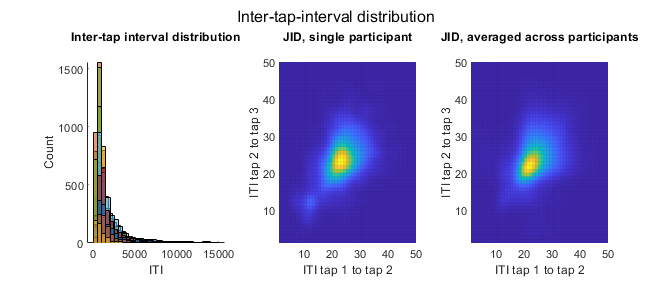

nbinsJID = 50;
edge_alpha = 0.05;

nBinsHistogram = 30;

f = figure;
f.Units = "inches";
f.Position = [ 3.7, 9.3, 7, 3 ];
sgtitle({'Inter-tap-interval distribution', ''});

tiledlayout(1, 3, "TileSpacing", "normal", "Padding", "normal");

% Histogram of ITIs
nexttile;
title({'', 'Inter-tap interval distribution', ''});
hold on;
cellfun(@(x) histogram(x(x < 15000), nBinsHistogram), inter_tap_intervals, 'UniformOutput', false);
hold off;

xlabel("ITI");
ylabel("Count");

%%% TODO: Replace histogram with density plot



% Single JID plot
jid_single = PlottingFunctions.iti2JID(inter_tap_intervals{1}', 'Bins', nbinsJID);

nexttile;

jid_plot_single = pcolor(jid_single);
jid_plot_single.EdgeAlpha = edge_alpha;
title({'', 'JID, single participant', ''});
xlabel("ITI 1");
ylabel("ITI 2");

% Average JID plot
jid_multi = zeros(nbins, nbins, size(betas, 4));

for ppt = 1:size(jid_multi, 3)
    jid_multi(:, :, ppt) = PlottingFunctions.iti2JID(inter_tap_intervals{ppt}', 'Bins', nbinsJID);
end

jid_average = mean(jid_multi, 3);

nexttile;

jid_plot_avg = pcolor(jid_average);
jid_plot_avg.EdgeAlpha = edge_alpha;
title({'', 'JID, averaged across participants', ''});
xlabel("ITI 1");
ylabel("ITI 2");

saveas(f, fullfile("figures", "hist_JID"), 'svg');

### Figure 2

### ERP plots

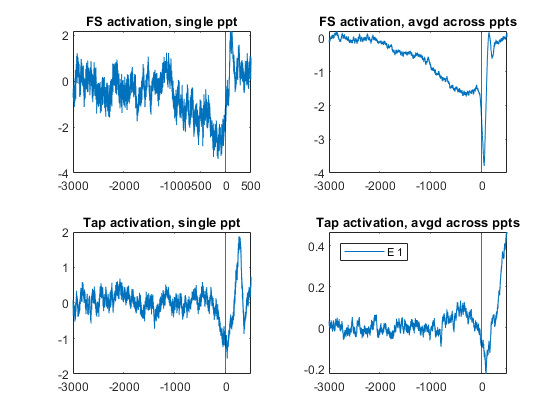

participant = 2;
time_points = -2999:500;
electrodes = 1;

xlims = [-3000, 500];
xticks_values = [-3000, -2000, -1000, -500, 0, 500];

figure;
tiledlayout(2, 2);

% Force sensor
nexttile;
plot(time_points, squeeze(avg_activation_FS(electrodes, :, participant))');
xlim(xlims);
xticks(xticks_values);
xline(0);
title("FS activation, single ppt");

nexttile;
plot(time_points, squeeze(mean(avg_activation_FS(electrodes, :, :), 3))');
xlim(xlims);
xline(0);
title("FS activation, avgd across ppts");

% Smartphone taps
nexttile;
plot(time_points, squeeze(avg_activation_Tap(electrodes, :, participant))');
xlim(xlims);
xline(0);
title("Tap activation, single ppt");

nexttile;
plot(time_points, squeeze(mean(avg_activation_Tap(electrodes, :, :), 3))');
xlim(xlims);
xline(0);
title("Tap activation, avgd across ppts");
legend(sprintf("E %d", electrodes), 'location', 'northwest');

Alternative plots, all in one

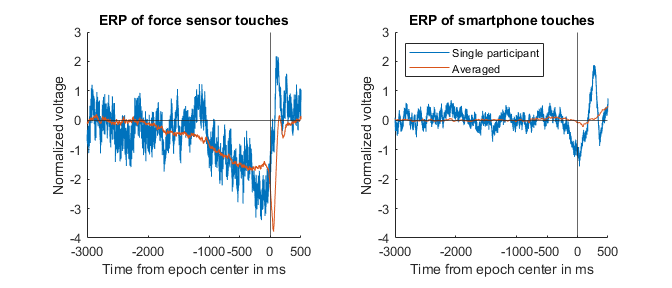

f = figure;
f.Units = "inches";
f.Position = [ 3.7, 9.3, 7, 3 ];
tiledlayout(1, 2);

nexttile;
hold on;
title("ERP of force sensor touches")
plot(time_points, squeeze(avg_activation_FS(electrodes, :, participant))');
plot(time_points, squeeze(mean(avg_activation_FS(electrodes, :, :), 3))');
xlim(xlims);
xticks(xticks_values);
xline(0);
yline(0);

xlabel("Time from epoch center in ms");
ylabel("Normalized voltage");

ylims_FS = ylim;

nexttile;
hold on;
title("ERP of smartphone touches")
plot(time_points, squeeze(avg_activation_Tap(electrodes, :, participant))');
plot(time_points, squeeze(mean(avg_activation_Tap(electrodes, :, :), 3))');
xlim(xlims);
xticks(xticks_values);
xline(0);
yline(0);

xlabel("Time from epoch center in ms");
ylabel("Normalized voltage");

ylim(ylims_FS)

legend({"Single participant", "Averaged"}, 'location', 'northwest');

saveas(f, fullfile("figures", "ERP_plots_2tiled"), 'svg');

### Topoplots of activation

Topoplots of FS  and smartphone touch activation over time

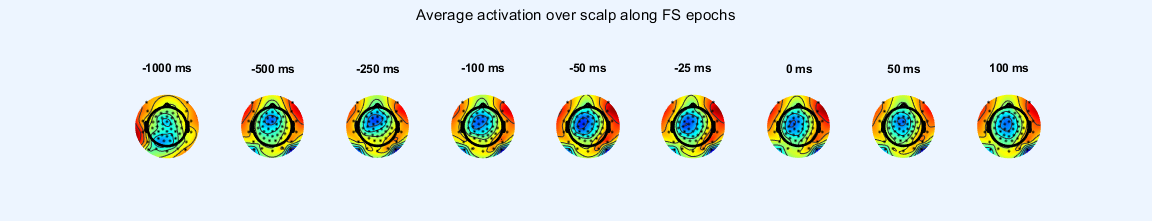

% Setup

data_size = size(avg_activation_FS);
%time_step = 500;
epoch_center = 3000;

which_ppt = 1;

sample_times = unique([1, time_step:time_step:data_size(2), data_size(2)]);

sample_times = [2000, 2500, 2750, 2900, 2950, 2975, 3000, 3050, 3100];
sample_times_text = sample_times - epoch_center;



% FS topo
f = figure;
f.Units = "inches";
f.Position = [ 3.7, 9.3, 12, 2.3 ];

sgtitle("Average activation over scalp along FS epochs");
tiledlayout(1, 9);

sampled_data = squeeze(avg_activation_FS(:, sample_times, which_ppt));

for time_slice = 1:size(sampled_data, 2)
    warning ('off','all');
    nexttile;
    title({'', sprintf("%d ms", sample_times_text(time_slice)), ''});
    topoplot(sampled_data(:, time_slice), expected_chanlocs);
end

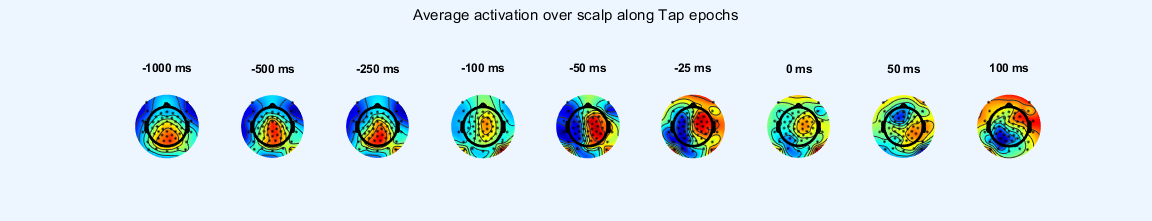


%% ADD TEMPERATURE LEGEND


% Smartphone tap topo
f = figure;
f.Units = "inches";
f.Position = [ 3.7, 9.3, 12, 2.3 ];

sgtitle("Average activation over scalp along Tap epochs");
tiledlayout(1, 9);

sampled_data = squeeze(avg_activation_Tap(:, sample_times, which_ppt));

for time_slice = 1:size(sampled_data, 2)
    nexttile;
    title({'', sprintf("%d ms", sample_times_text(time_slice)), ''});
    topoplot(sampled_data(:, time_slice), expected_chanlocs);
end


warning ('on','all');

### Figure 3

### Beta plots

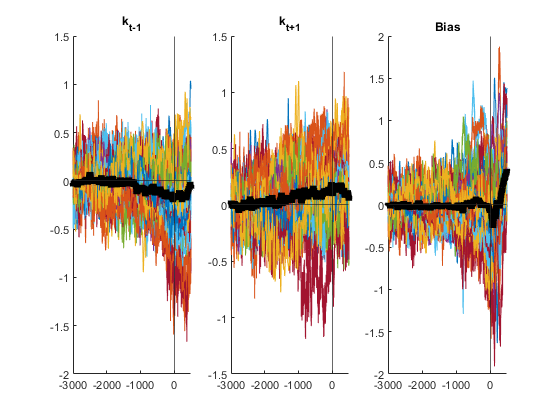

titles = ["k_t-1", "k_t+1", "Bias"];

use_trimmed_mean = true;

f = figure;
f.Units = "inches";
f.Position = [ 3.7, 9.3, 12, 4 ];

sgtitle("Mean beta values");    
tiledlayout(1, 3);

for beta = 1:size(betas, 3)
    nexttile;
    hold on;
    
    % Single participant waves
    plot(epoch_size(1) * 1000 + 1:epoch_size(2) * 1000, squeeze(betas(maximum_electrode, :, beta, :)));
    
    
    % Add mean line
    if use_trimmed_mean
        electrode_values = squeeze(betas(maximum_electrode, :, beta, :));
        electrode_values = sort(electrode_values, 2);
        mean_indices = floor(size(electrode_values, 2) * 0.1):ceil(size(electrode_values, 2) * 0.9);
        mean_line = mean(electrode_values(:, mean_indices), 2);
    else
        mean_line = mean(squeeze(betas(maximum_electrode, :, beta, :)), 2);
    end
    
    plot(epoch_size(1) * 1000 + 1:epoch_size(2) * 1000, mean_line, 'LineWidth', 5, 'color', [0, 0, 0]);
    
    
    t = title(["", betas_names{beta}]);
    %t.Position = [ t.Position(1), -2.5, t.Position(3) ];
    
    xline(0);
    yline(0);
    xlim(epoch_size * 1000);
    
    xlabel("Time in milliseconds");
    ylabel("\beta");
end

saveas(f, fullfile("figures", "beta_plot"), 'svg');

### Topoplot of thresholded t-values

Averaged across participants

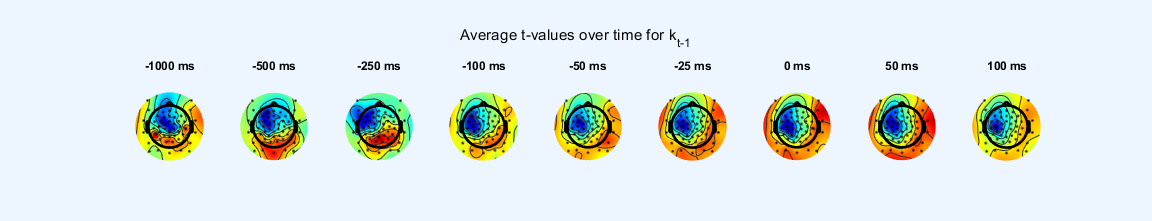

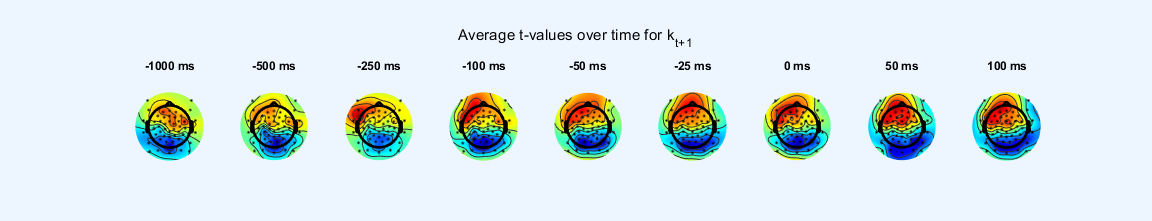

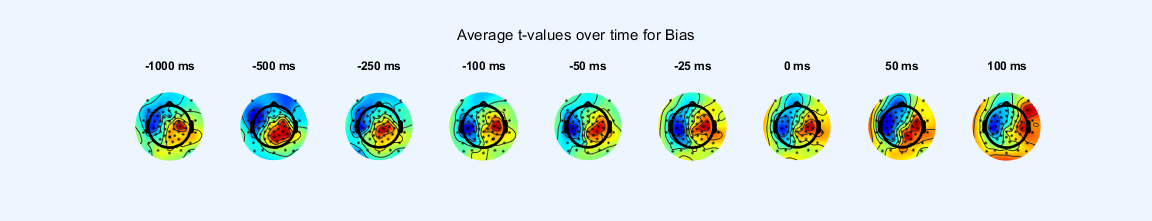

titles = ["k_t-1", "k_t+1", "Bias"];

for beta = 1:size(one_sample, 4)
    % Smartphone tap topo
    f = figure;
    f.Units = 'inches';
    f.Position = [ 3.7, 9.3, 12, 2.3 ];
    
    sgtitle({"", sprintf("Average t-values over time for %s", betas_names{beta}), ""});
    tiledlayout(f, 1, 9, 'TileSpacing', 'compact');
    
    sampled_data = squeeze(one_sample(:, sample_times, 4, beta));
    
    for time_slice = 1:size(sampled_data, 2)
        nexttile;
        title({'', sprintf("%d ms", sample_times_text(time_slice)), ''});
        topoplot(sampled_data(:, time_slice), expected_chanlocs);
    end
    
    saveas(f, sprintf("%s%savg_t_values_%d", "figures", filesep, beta), 'svg');
end

### Significant clusters plot

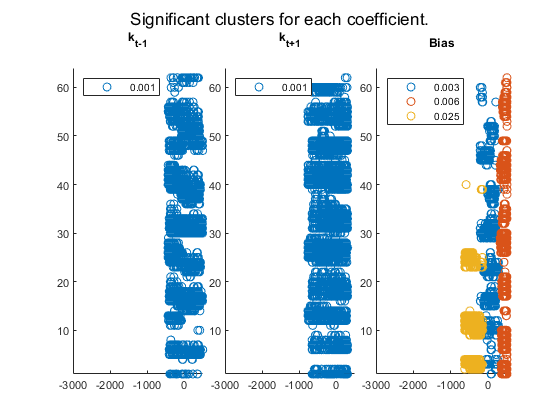

figure;
sgtitle('Significant clusters for each coefficient.')
tiledlayout(1, 3, 'TileSpacing', 'compact')


for current_beta = 1:size(mask, 3)
    clusters = unique(mask(:, :, current_beta))';
    clusters(clusters == 0) = []; % Remove 0, 0 is no significant cluster
    
    ax = nexttile;
    title({"", sprintf("%s", betas_names{current_beta}), ""});
    
    hold on;
    xlim(epoch_size * 1000);
    ylim([1, size(mask, 1)]);
    
    this_beta_cluster_ps = {};
    
    for current_cluster = clusters
        cluster_indices = squeeze(mask(:, :, current_beta)) == current_cluster;
        [cluster_pos_x, cluster_pos_y] = find(cluster_indices');
        
        hold on;
        scatter(cluster_pos_x + (epoch_size(1) * 1000), cluster_pos_y);
        
        this_cluster_p = squeeze(cluster_p(:, :, current_beta));
        this_beta_cluster_ps{current_cluster} = string(max(this_cluster_p(cluster_indices)));
    end
    
    l = legend(this_beta_cluster_ps, 'location', 'northwest');
end







for current_beta = 1:size(mask, 3)
    figure;
    
    
end





### EFG Plots

Topoplot of thresholded t-values (according to significant clusters)

Local function

function latencies = iti2latency(itis, varargin)
    p = inputParser;
    addRequired(p, 'itis');
    addOptional(p, 'offset', 0);
    parse(p, itis, varargin{:});
    
    offset = p.Results.offset;
    
    latencies = zeros(length(itis), 1);
    latencies(1) = offset;
    
    for i = 2:length(itis)
        latencies(i) = latencies(i - 1) + itis(i - 1);
    end
end